## MSE 491 DSP: Project 2 - Filter Design

Authors:

- Abdullah Amjad - 301414558

- Tony Nguyen - 301286979

Created: 24 Jul 2022

Modified: 24 Jul 2022

clear all
close all
clc

## Loading Variables

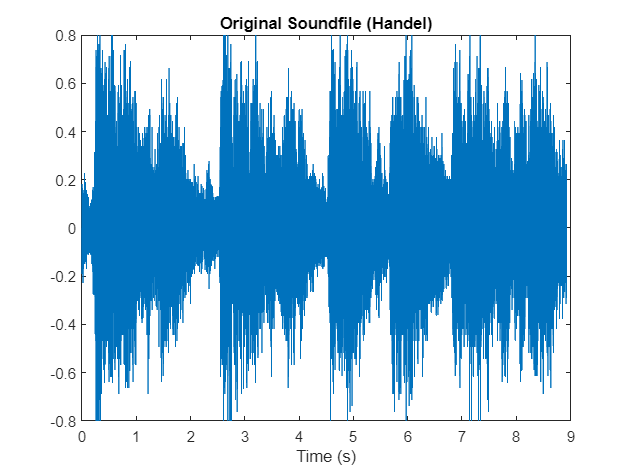

% Setting global variables
% Import carrier signal
global y Fs Ts N t current previous
load Handel

Ts = 1/Fs;
N = length(y);
t = [0:N-1]*Ts; t = t(:);
current = y;

%sound(y,Fs)
figure
plot(t,y);title('Original Soundfile (Handel)');
xlabel('Time (s)');

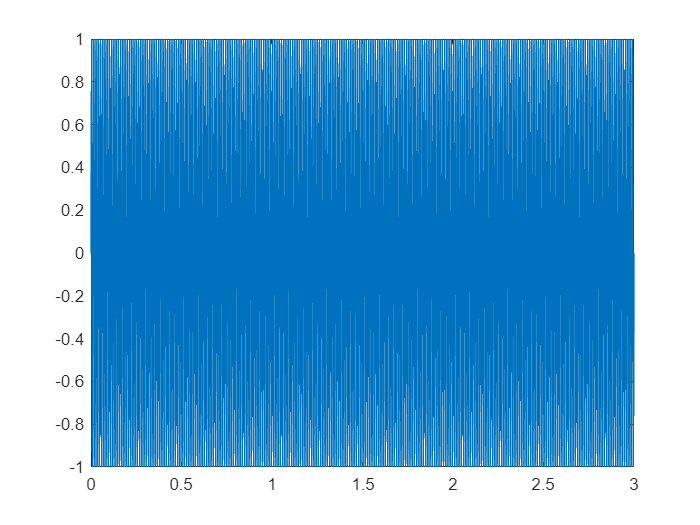

% Alternate audio loading - Sine wave that is easier to visualize audio effects
global y Fs Ts N t current previous

Fs = 48000;
Ts = (1/Fs);
t = 0:Ts:3;
t = t(:);
f = 100; phi = 0;
y = sin(2*pi*f.*t + phi);
N = length(y);
current = y;

figure(1);
plot(t,y);

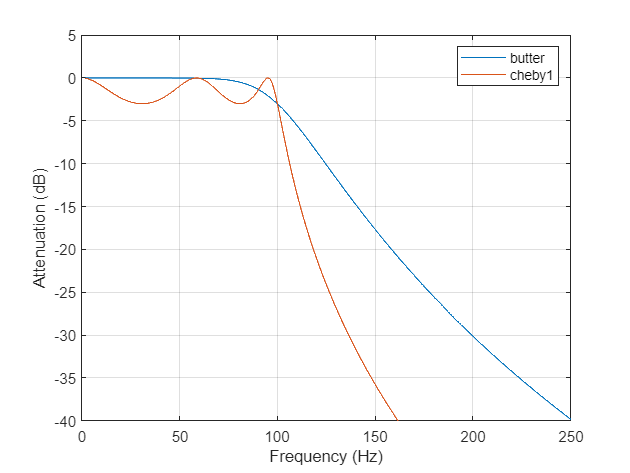

%% Analogue Filters
% Butterworth
n = 5; %order of filter
fc = 100; %cutoff freq in Hz
Wn = 2*pi*fc; %cutoff angular frequency, need to input 's' as last function input
ns = N; %number of test points for filters

%% Type of filter
% 'low': lowpass with cutoff frequency Wn
% 'high': highpass with cutoff frequency Wn.
% 'bandpass': bandpass  of order 2n if Wn is two-element vector
% 'stop': bandstop of order 2n if Wn is two-element vector
ftype = 'low';

%% Filter function outputs
% z - zeros of filter's transfer function
% p - poles of filter's transfer function
% k - filter gain
[zbu,pbu,kbu] = butter(n,Wn,ftype,'s');

%% zp2tf - Convert zero-pole-gain filter parameters to transfer function form
% b - numerator coefficients of transfer function
% a - denominator coefficients of transfer function
[bbu,abu] = zp2tf(zbu,pbu,kbu);

%% freqs - Frequency response of analog filters
% n - number of evaluation points
% h - frequecy response
% w - angular frequencies at which h is computed
[hbu,wbu] = freqs(bbu,abu,ns);

% % Bessel - do not use this
% [zbe,pbe,kbe] = besself(n,Wn,ftype);
% [bbe,abe] = zp2tf(zbe,pbe,kbe);
% [hbe,wbe] = freqs(bbe,abe,ns);

%% Chebyshev
% I
Rp = 3; %pk-to-pk bandpass ripple in dB
Wp = Wn; %passband edge freq

[z1,p1,k1] = cheby1(n,Rp,Wp,ftype,'s');
[b1,a1] = zp2tf(z1,p1,k1);
[h1,w1] = freqs(b1,a1,ns);

% % II - Don't use this :(
% Rs = 30; %stopband attenuation in dB
% 
% [z2,p2,k2] = cheby2(n,Rs,Wp,ftype,'s');
% [b2,a2] = zp2tf(z2,p2,k2);
% [h2,w2] = freqs(b2,a2,ns);

%% Plot phase of the filter
figure
plot(wbu/(2*pi),mag2db(abs(hbu)))
hold on
% plot(wbe/(fc*pi),mag2db(abs(hbe)))
plot(w1/(2*pi),mag2db(abs(h1)))
% plot(w2/(f*pi),mag2db(abs(h2)))
axis([0 2.5*fc -40 5])
grid
xlabel('Frequency (Hz)')
ylabel('Attenuation (dB)')
legend('butter','cheby1')

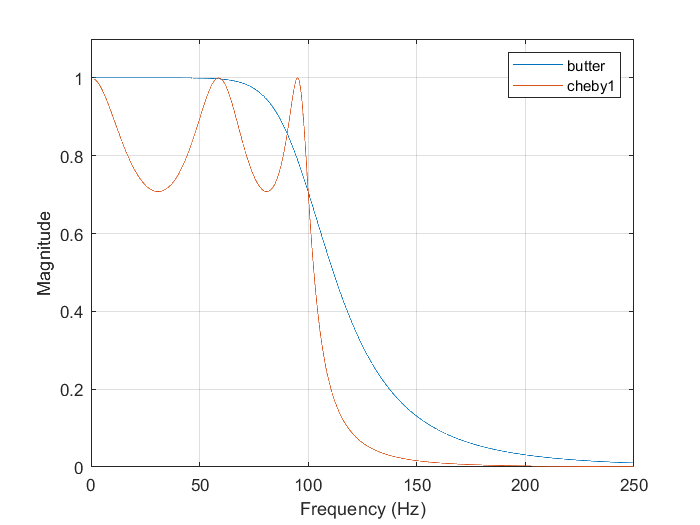


figure
plot(wbu/(2*pi),abs(hbu))
axis([0 2.5*fc 0 1.1])
grid
hold on
plot(w1/(2*pi),abs(h1))
xlabel('Frequency (Hz)')
ylabel('Magnitude')
legend('butter','cheby1')

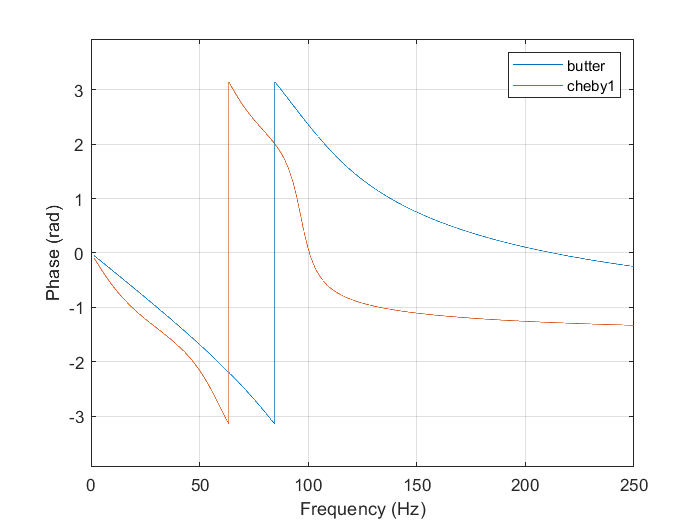


figure
plot(wbu/(2*pi),angle(hbu))
hold on
axis([0 2.5*fc -(max(angle(hbu))*1.25) (max(angle(hbu))*1.25)])
grid
plot(w1/(2*pi),angle(h1))
xlabel('Frequency (Hz)')
ylabel('Phase (rad)')
legend('butter','cheby1')

y_f = conv(y,h1)

y_f =    0.0000 + 0.0000i
  -0.0061 + 0.0006i
  -0.0805 + 0.0084i
  -0.1114 + 0.0116i
  -0.1053 + 0.0109i
  -0.0675 + 0.0070i
  -0.0488 + 0.0051i
  -0.0736 + 0.0076i
  -0.1045 + 0.0109i
  -0.1789 + 0.0186i



figure
plot(t,y_f)

Error using plot
Vectors must be the same length.

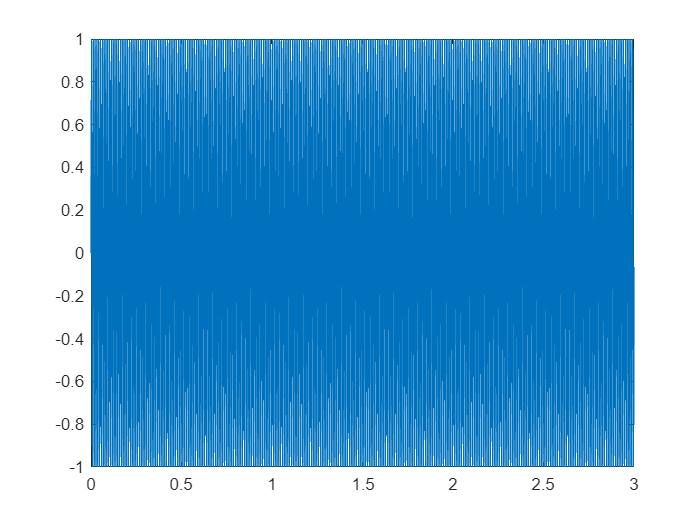

%% Digital Filters
% Moving Average
L = 11; %length of window
b = ones(L,1)/L; %numerator coefficients of transfer function
a = 1; %denominator coefficients of transfer function
MvgAvg = filter(b, a, y);

%need to FFT filtered value to get freq-response of system

%plot moving avg in time domain
figure
plot(t, MvgAvg)

## Windowed-Sinc

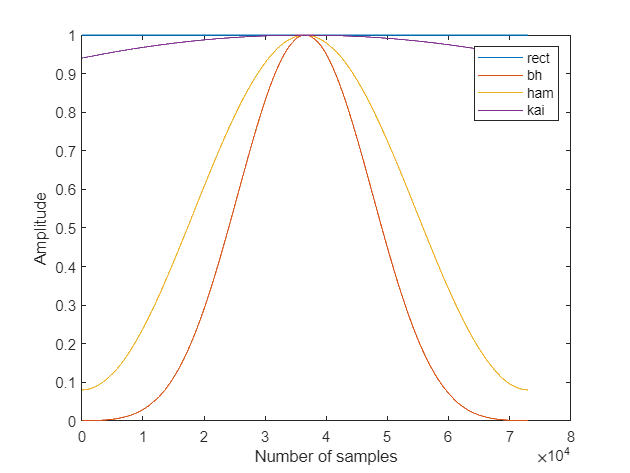

fc = 0.25; %fraction of sampling rate between 0 - 0.5
L = N;
n = (1:L);

%% Window Functions
% Rectuangular
w_rect = rectwin(L);

% Blackman-Harris
w_bh = blackmanharris(L);

% Hamming
w_h = hamming(L);

% Kaiser
beta = 0.5; %shape factor, leave at default value of 0.5
w_k = kaiser(L,beta);

figure
plot(n, w_rect)
hold on
plot (n, w_bh)
plot (n, w_h)
plot (n, w_k)
xlabel('Number of samples')
ylabel('Amplitude')
legend('rect','bh','ham','kai')

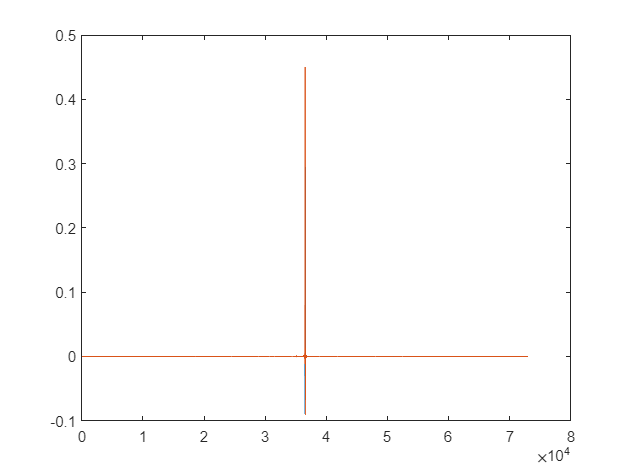

window = transpose(w_bh);
window = w_bh;

sinc_nw = 2*fc*sinc(2*fc*(n-L/2));
sinc_w = sinc_nw'.*window;
figure
plot(n, sinc_nw)
hold on
plot(n, sinc_w)

% Plot input signal in frequency domain
Y = fft(y,N).';
P2 = abs(Y/N); %normalized magnitude
% P2 = abs(Y); %non-normalized magnitude
P1 = P2(1:(N/2+1));

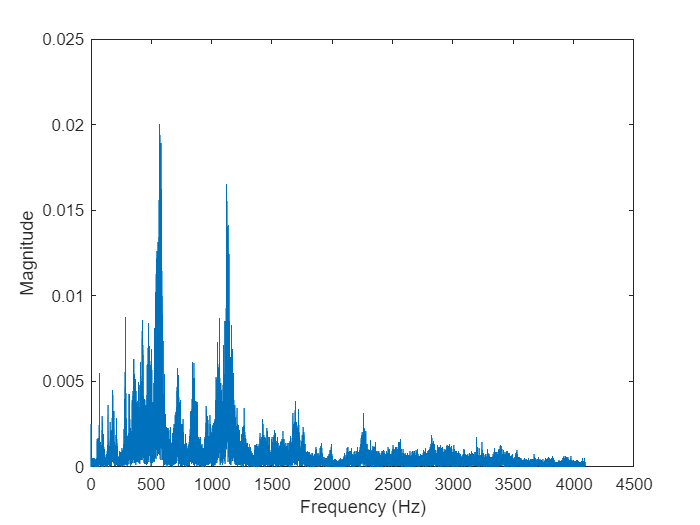

P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(N/2))/N;

figure 
plot(f,P1)
xlabel('Frequency (Hz)')
ylabel('Magnitude')

P1 = Y(1:(N/2+1));

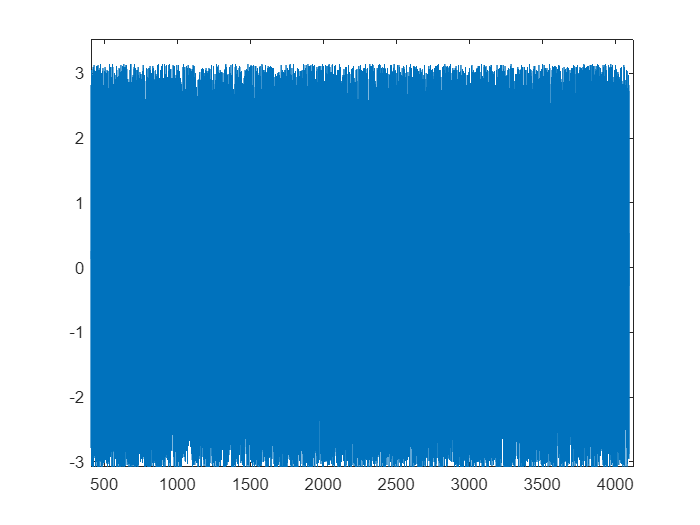

figure
plot(f,angle(P1))

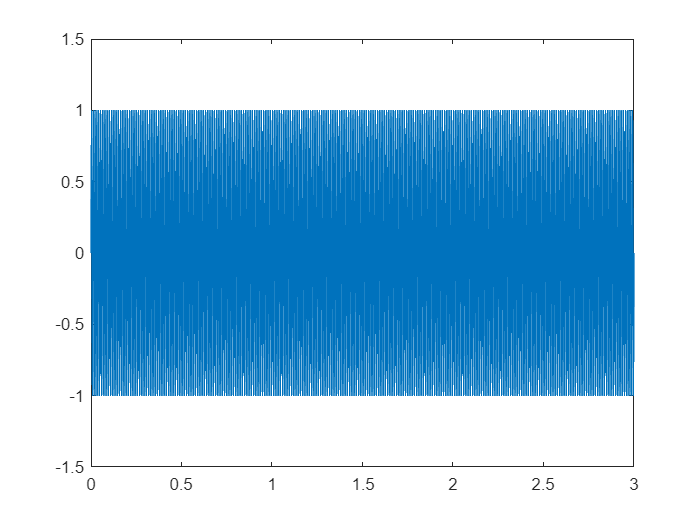

X = ifft(Y);

figure
plot(t,X)